# **混沌游戏chaosgame**

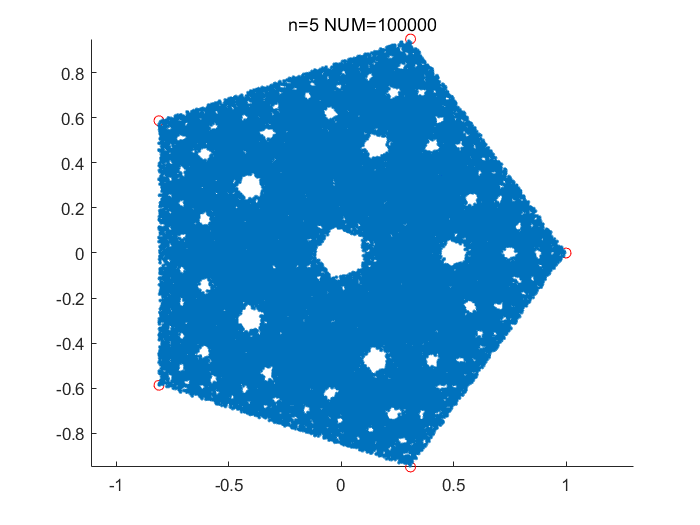

n=5;index =5;
N=zeros(n,2);%N记录动点坐标
NUM=10^index;
for i=1:n
    theta=pi*2/n;
    N(i,:)=[cos(i*theta),sin(i*theta)];
end 
now=rand(1,2);    
p=zeros(NUM,2);%p记录动点坐标
clf;
hold on;axis equal;
plot(N(:,1),N(:,2),'ro');
plot(now(1),now(2),'bx');  
for i=1:NUM
    x=ceil(rand()*n);
    aim=N(x,:);
    m=0.5;%rand();
    vec=aim-now;
    now=vec*m+now;
    p(i,:)=now;
end
plot(p(:,1),p(:,2),'.');axis equal;
title(strcat('n=',num2str(n),' NUM=',num2str(NUM)));
hold off;